# Tendencia

## Descarga datos

url = 'https://gml.noaa.gov/webdata/ccgg/trends/co2/co2_mm_mlo.csv';
opts = detectImportOptions(url, 'Delimiter', ',', 'CommentStyle', '#');
T = readtable(url, opts);    % Lee directo desde la URL

head(T)

    year    month    decimalDate    average    deseasonalized    ndays    sdev      unc 
    ____    _____    ___________    _______    ______________    _____    _____    _____

    1958      3        1958.2       315.71         314.44         -1      -9.99    -0.99
    1958      4        1958.3       317.45         315.16         -1      -9.99    -0.99
    1958      5        1958.4       317.51         314.69         -1      -9.99    -0.99
    1958      6        1958.5       317.27         315.15         -1      -9.99    -0.99
    1958      7        1958.5       315.87          315.2         -1      -9.99    -0.99
    1958      8        1958.6       314.93         316.21         -1      -9.99    -0.99
    1958      9


% url_2 = 'https://scrippsco2.ucsd.edu/assets/data/atmospheric/stations/in_situ_co2/monthly/monthly_in_situ_co2_mlo.csv'
% opts_2 = detectImportOptions(url_2, 'Delimiter', ',', 'CommentStyle', '#');
% T_2 = readtable(url_2, opts_2);    % Load second dataset
% head(T_2)
% T_2 = T_2(T_2.CO2_1 > 0, :)
% head(T_2)


Seguimos

T.Fecha = datetime(T.year, T.month, 1)

T = 810×9 table
    year    month    decimalDate    average    deseasonalized    ndays    sdev      unc        Fecha   
    ____    _____    ___________    _______    ______________    _____    _____    _____    ___________

    1958      3        1958.2       315.71         314.44         -1      -9.99    -0.99    01-Mar-1958
    1958      4        1958.3       317.45         315.16         -1      -9.99    -0.99    01-Apr-1958
    1958      5        1958.4       317.51         314.69         -1      -9.99    -0.99    01-May-1958
    1958      6        1958.5       317.27         315.15         -1      -9.99    -0.99    01-Jun-1958
    1958      7        1958.5       315.87          3

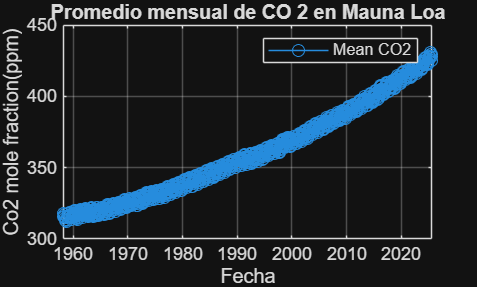


% Graficar los promedios mensuales
figure;
plot(T.Fecha, T.average, '-o', 'DisplayName', 'Mean CO2');

% Añadir etiquetas y leyenda
xlabel('Fecha');
ylabel('Co2 mole fraction(ppm)');
title('Promedio mensual de CO 2 en Mauna Loa');
legend show;
grid on;

Ahora ajustamos a una regresion lineal

tiempo_num = datenum(T.Fecha);
tiempo_num_2 = 1:length(T.Fecha);


model_lineal = polyfit(tiempo_num, T.average, 1)

model_lineal = 1.0e+03 *

    0.0000   -2.9370


model_lineal_2 = polyfit(tiempo_num_2, T.average, 1)

model_lineal_2 =     0.1380  304.4244


modelo_cuadratico_1 = polyfit(tiempo_num, T.average, 2)

modelo_cuadratico_1 = 1.0e+04 *

    0.0000   -0.0000    5.0540


modelo_cuadratico_2 = polyfit(tiempo_num_2, T.average, 2)

modelo_cuadratico_2 =     0.0001    0.0620  314.6989




output_model_1 = polyval(model_lineal, tiempo_num);
output_model_2 = polyval(model_lineal_2, tiempo_num_2);
output_model_cuad_1 = polyval(modelo_cuadratico_1, tiempo_num);
output_model_cuad_2 = polyval(modelo_cuadratico_2, tiempo_num_2);

Graficando

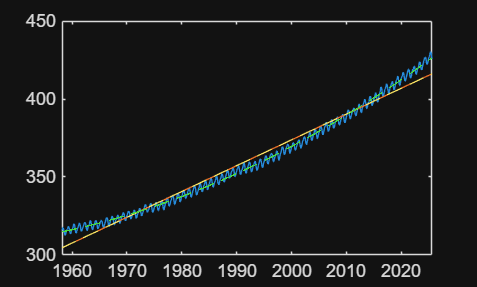

figure;
plot(T.Fecha, T.average)
hold on;
plot(T.Fecha, output_model_1)
hold on;
plot(T.Fecha, output_model_2, '--', 'DisplayName', 'Modelo Lineal 2');
hold on;
plot(T.Fecha, output_model_cuad_1, '--', 'DisplayName', 'Modelo Cuadrático 1');
hold on;
plot(T.Fecha, output_model_cuad_2, '--', 'DisplayName', 'Modelo Cuadrático 2');
hold off;

   Removiendo tendencias

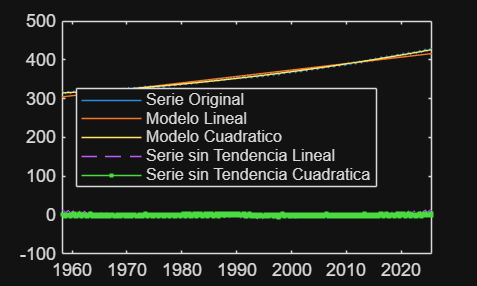


serie_sin_tendencia_lineal = T.average - output_model_1;
serie_sin_tendencia_cuadratica = T.average - output_model_cuad_1;


figure;
plot(T.Fecha, T.average, "DisplayName", "Serie Original")
hold on;
plot(T.Fecha, output_model_1, "DisplayName", "Modelo Lineal")
hold on;
plot(T.Fecha, output_model_cuad_1, "DisplayName", "Modelo Cuadratico")
hold on;
plot(T.Fecha, serie_sin_tendencia_lineal, '--', 'DisplayName', 'Serie sin Tendencia Lineal');
hold on;
plot(T.Fecha, serie_sin_tendencia_cuadratica, '.-', 'DisplayName', 'Serie sin Tendencia Cuadratica');
legend('Location',"west")
hold off;

Functions

function scr = scr_function(y_fitted, y_mean)
    
   scr = sum((y_fitted - y_mean).^2);
    
end

function sce = sce_function(y_fitted, y_observed)

   sce = sum((y_fitted - y_observed).^2);

end

function sct = sct_function(sce, scr)

    sct = sce + scr;

end

function determinante = determinante_coef(scr, sct)

    determinante = scr/sct;

end



Aplicando Suma de Cuadrados Totales al cuadrático

scr_data_cuad = scr_function(output_model_cuad_1, mean(T.average));
sce_data_cuad = sce_function(output_model_cuad_1, T.average);
sct_data_cuad = sct_function(scr_data_cuad, sce_data_cuad);
determinante_cuad = determinante_coef(scr_data_cuad, sct_data_cuad);

display(determinante_cuad)

determinante_cuad = 0.9953

Aplicando Suma de Cuadrados Totales al linea

scr_data_lineal = scr_function(output_model_1, mean(T.average));
sce_data_lineal = sce_function(output_model_1, T.average);
sct_data_lineal = sct_function(scr_data_lineal, sce_data_lineal);
determinante_lineal = determinante_coef(scr_data_lineal, sct_data_lineal);

display(determinante_lineal)

determinante_lineal = 0.9756

Using FitLM

mdl = fitlm(tiempo_num,T.average)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE         tStat     pValue
                   _________    __________    _______    ______

    (Intercept)        -2937        18.329    -160.23      0   
    x1             0.0045323    2.5193e-05      179.9      0   


Number of observations: 810, Error degrees of freedom: 808
Root Mean Squared Error: 5.1
R-squared: 0.976,  Adjusted R-Squared: 0.976
F-statistic vs. constant model: 3.24e+04, p-value = 0

mdl.Rsquared.Ordinary

ans = 0.9756

mdl.Rsquared.Adjusted

ans = 0.9756